# Honours Live Script 2

## Load and Save Data

if ~exist("workspaceVarHonours", 'var')
    load matlabHonours.mat
    setInterpLatex()
end

if exist("workspaceVarHonours", 'var')
    clearVarsArray = clearVars();
    clear(clearVarsArray{:})
    clear clearVarsArray
    save matlabHonours.mat
end 

% set the default intepreter to latex
setInterpLatex()

## Contents

Model Dynamics Testing

Stochasticity Testing

Loading In Coral Trout Data

Plotting Tools

MPT Decision Coding

Coding Decision Methods

## Assumptions Made

% I found online somewhere that that |cov(X, Y)| < max(var(X), var(Y))
% which I used in my MPT() function coding

% another assumption I made for that code is that in the continuous
% investment case, I have assumed that all of the resources must be
% invested, in order to set limits on the above and below limits on
% expected returns and variances, in order to allow the weightings to be
% useful

% one thing to note is the code in ExtractGBR - it seems to just find the
% reef closest to the final point of the larvae, which is clearly
% potentially a bit flawed but it could simply be that the particle tracks
% already take into account the reef proximity in some way

% need to ensure that 

## Model Dynamics Testing

% I want to do a bunch of runs of the metapopulation model to ensure that
% it is working as intended / expected -> I'll use the same IC's for each
% of the tests, and then look at how the populations change once I start
% altering the connectivity

% let's start with uniform populations across the reefs, that way we can
% really see how the system equilibrium turns out
unifPop = [200, 100, 80, 75];
popInit = repmat(unifPop, [3, 1]);

### Standard Model

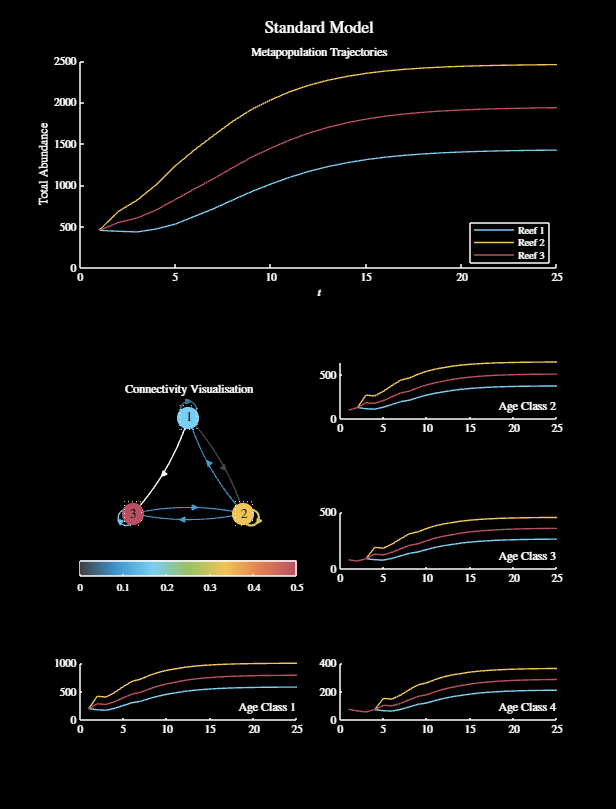

% start by running the model with a connectivity matrix that I decided
% arbitrarily
specStruct.alpha = 1.5 * 10^-5;
specStruct.beta = 1 * 10^-8;
specStruct.successVec = [0.65, 0.7, 0.8];
specStruct.fecundVec = 10^5 * [0, 2, 4, 6];
tMax = 25;
conMat = [0.05, 0.007, 0.001; 0.09, 0.3, 0.09; 0, 0.09, 0.15];
popMat = baseMetapopModel(conMat, areaVec, popInit, tMax, specStruct);

% visualise the stuff -> create a function
tL = visualiseMetapop(popMat, 1:tMax, conMat);
title(tL, "Standard Model")
darkFig(tL)
figResize(1.75)

### 2 With Self Recruitment, 1 With None

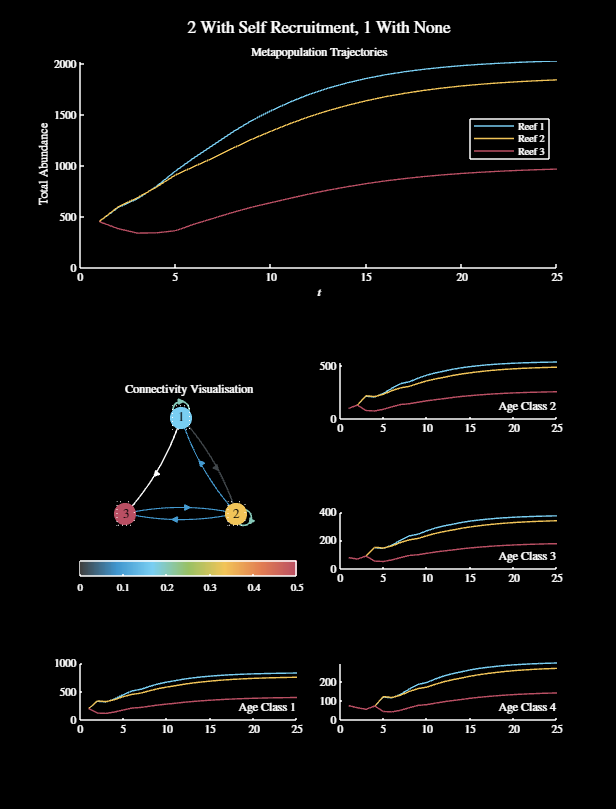

% alter the self recruitment levels
tMax = 25;
conMat = [0.2, 0.007, 0.001; ...
    0.09, 0.2, 0.09; ...
    0, 0.09, 0];
popMat = baseMetapopModel(conMat, areaVec, popInit, tMax, specStruct);

% visualise the stuff -> create a function
tL = visualiseMetapop(popMat, 1:tMax, conMat);
title(tL, "2 With Self Recruitment, 1 With None")
darkFig(tL)
figResize(1.75)

### Self Recruitment Only

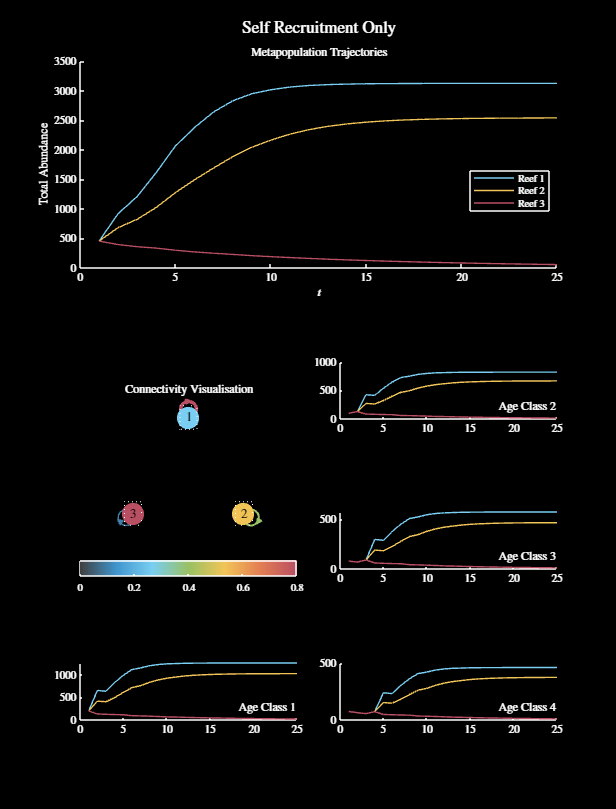

% alter the self recruitment levels
tMax = 25;
conMat = [0.8, 0, 0; ...
    0, 0.4, 0; ...
    0, 0, 0.1];
popMat = baseMetapopModel(conMat, areaVec, popInit, tMax, specStruct);

% visualise the stuff -> create a function
tL = visualiseMetapop(popMat, 1:tMax, conMat);
title(tL, "Self Recruitment Only")
darkFig(tL)
figResize(1.75)

### No Larval Exchange

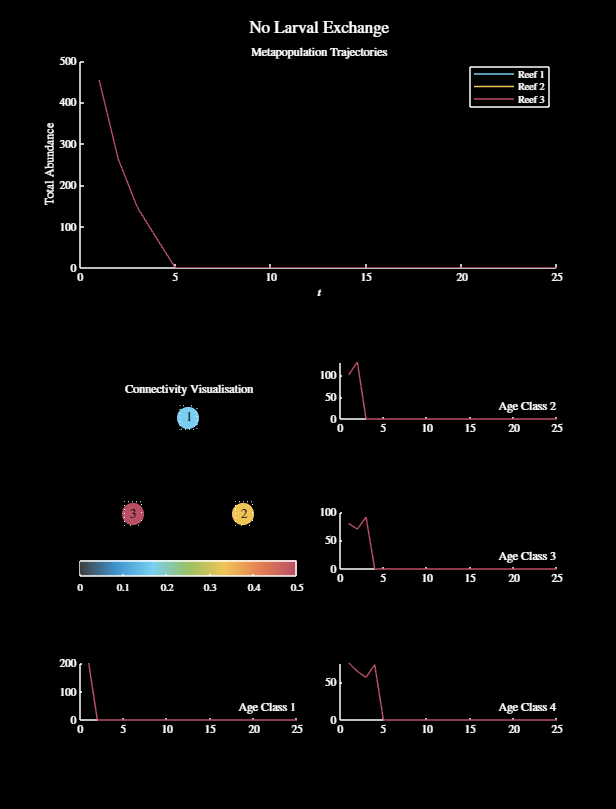

% alter the self recruitment levels
tMax = 25;
conMat = [0, 0, 0; ...
    0, 0, 0; ...
    0, 0, 0];
popMat = baseMetapopModel(conMat, areaVec, popInit, tMax, specStruct);

% visualise the stuff -> create a function
tL = visualiseMetapop(popMat, 1:tMax, conMat);
title(tL, "No Larval Exchange")
darkFig(tL)
figResize(1.75)

### No Self Recruitment

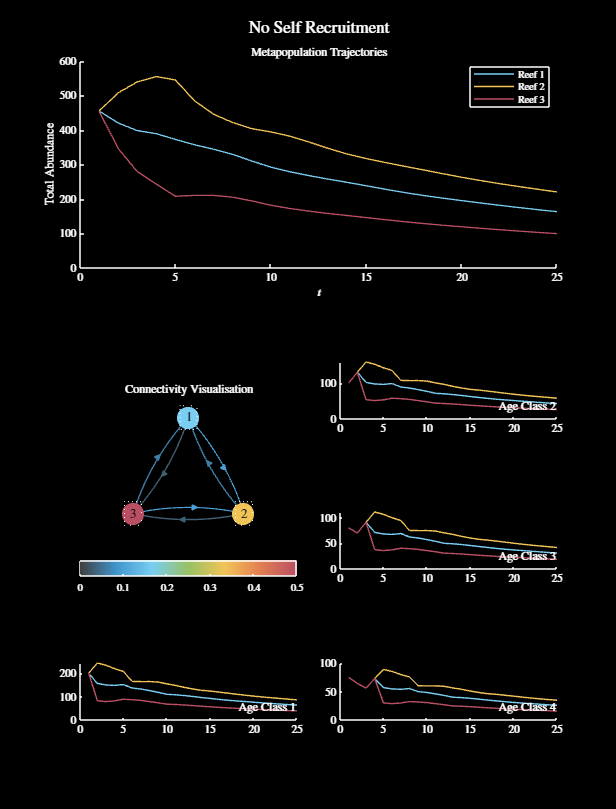

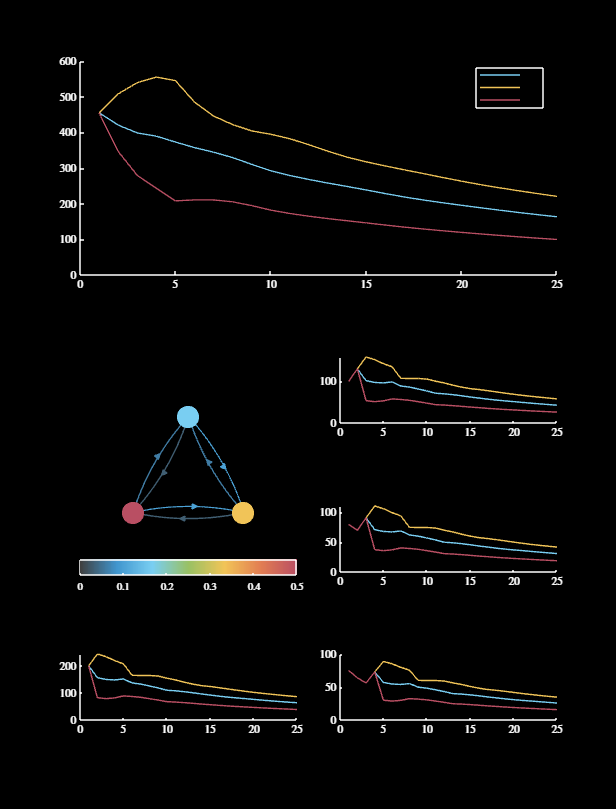

% alter the self recruitment levels
tMax = 25;
conMat = [0, 0.1, 0.03; ...
    0.06, 0, 0.03; ...
    0.06, 0.1, 0];
popMat = baseMetapopModel(conMat, areaVec, popInit, tMax, specStruct);

% visualise the stuff -> create a function
tL = visualiseMetapop(popMat, 1:tMax, conMat);
title(tL, "No Self Recruitment")
darkFig(tL)
figResize(1.75)

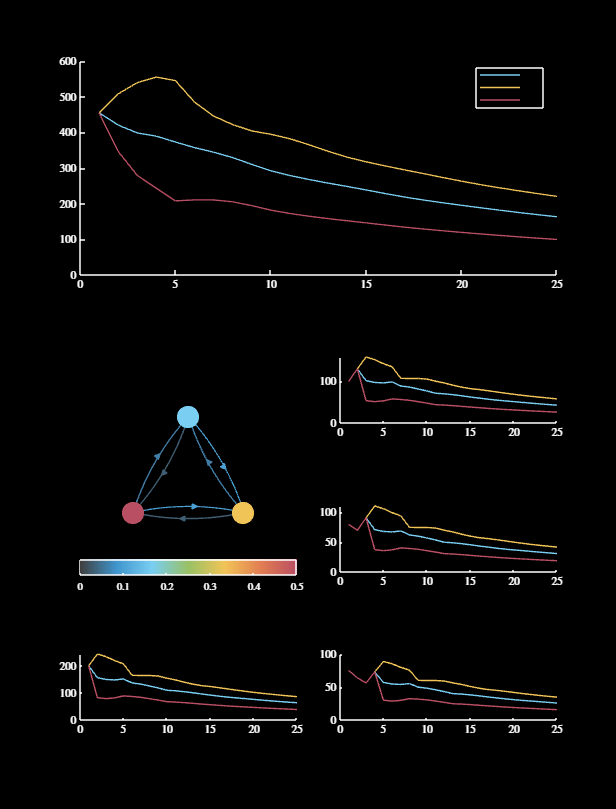

% alter the self recruitment levels
tMax = 25;
conMat = [0, 0.1, 0.03; ...
    0.06, 0, 0.03; ...
    0.06, 0.1, 0];
popMat = baseMetapopModel(conMat, areaVec, popInit, tMax, specStruct);

% visualise the stuff -> create a function
tL = visualiseMetapop(popMat, 1:tMax, conMat);
title(tL, "No Self Recruitment")
darkFig("colormap")
figResize(1.75)
saveCoolFig("MetapopSim", "labelsLegend")

### Hierarchical Connectivity

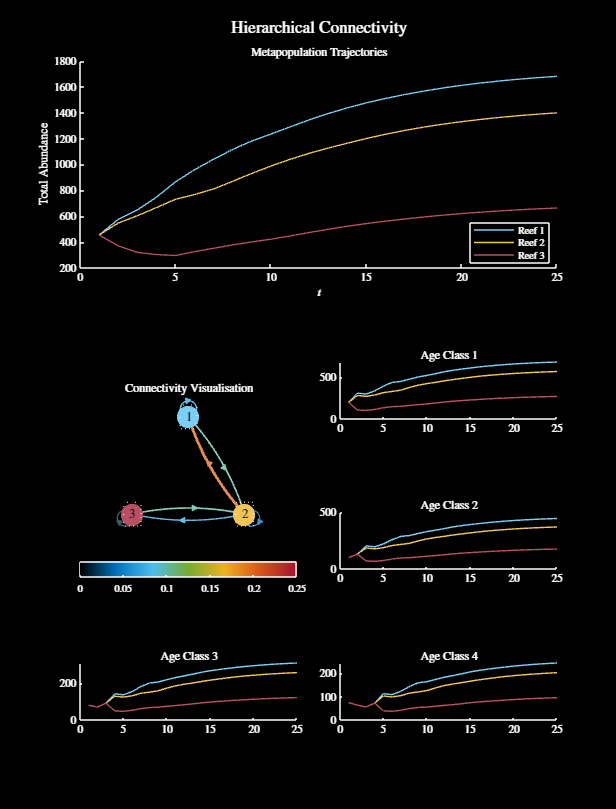

% alter the self recruitment levels
tMax = 25;
conMat = [0.07, 0.1, 0; ...
    0.2, 0.04, 0.07; ...
    0, 0.1, 0.01];
popMat = baseMetapopModel(conMat, areaVec, popInit, tMax, specStruct);

% visualise the stuff -> create a function
tL = visualiseMetapop(popMat, 1:tMax, conMat);
title(tL, "Hierarchical Connectivity", "Interpreter", 'L')
setFontSize(14)
darkFig(tL)
figResize(1.75)

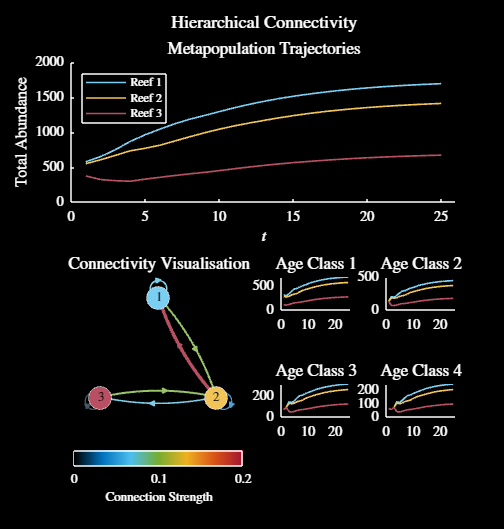

% look at creating a more horizontal figure instead for the progress
% reprort

% alter the self recruitment levels
tMax = 25;
conMat = [0.07, 0.1, 0; ...
    0.2, 0.04, 0.07; ...
    0, 0.1, 0.01];
popMat = baseMetapopModel(conMat, areaVec, popInit, tMax, specStruct);

% visualise the stuff -> create a function
tL = visualiseMetapop(popMat, 1:tMax, conMat, "horizontal");    
title(tL, "Hierarchical Connectivity", "Interpreter", 'L')
figResize(1.4)
setFontSize(12)

% save the figure
saveFig("threeReefHeirarchical")

% save a dark mode version of the figure
darkFig()
saveFig("threeReefHeirarchicalDM")

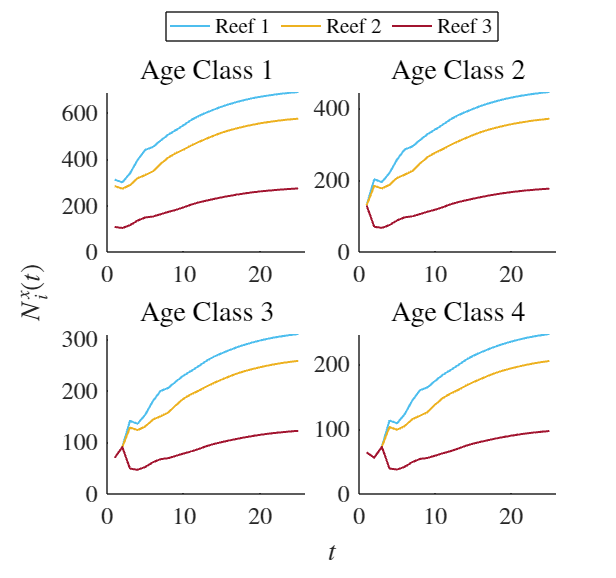

% create a more vertical figure for the presentation
% alter the self recruitment levels
tMax = 25;
conMat = [0.07, 0.1, 0; ...
    0.2, 0.04, 0.07; ...
    0, 0.1, 0.01];
popMat = baseMetapopModel(conMat, areaVec, popInit, tMax, specStruct);

% visualise the stuff -> create a function
textSize = 12;
nReefs = 3;
tVec = 1:tMax;
totPop = squeeze(sum(popMat, 2));
tL = tiledlayout(2, 2, "TileSpacing", "compact");

% now plot each of the age classes
nAges = 4;
for a = 1:min(4, nAges)

    % split the size of the panels based on whether we are dispaying the
    % connectivity matrix
    nexttile()
    
    % plot the stuff, with a dummy point so I can write the title as a
    % legend instead lmao
    hold on
    for r = 1:nReefs
        plot(tVec, squeeze(sum(popMat(r, a, :), 2)), 'color', ...
            getColour(r, nReefs), 'LineWidth', 1.5)
    end
    xlim([0, max(tVec) + 1])
    title(sprintf("Age Class %g", a), 'FontSize', textSize)

end

% add a legend
lG = legend("Reef 1", "Reef 2", "Reef 3", 'Location', 'layout', 'Orientation', 'horizontal');
lG.Layout.Tile = "North";
xlabel(tL, "$t$", 'Interpreter', 'Latex')
ylabel(tL, "$N_i^x (t)$", 'Interpreter', 'Latex')
figResize(1.25)
setFontSize(20)
saveFig("metapopExamplePP")

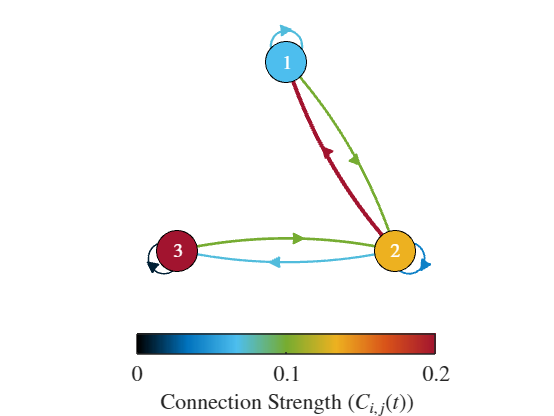

% plot the connectivity matrix visualisations
figure
visualiseConMat(conMat, "fig")
% title('Connectivity Visualisation', 'FontSize', 1.2 * textSize)
ax = gca;
ax.Colorbar.Location = 'southoutside';
ax.Colorbar.Label.String = "Connection Strength ($C_{i, j}(t)$)";
ax.Colorbar.Label.Interpreter = "Latex";
ax.Colorbar.Label.FontSize = textSize;

setFontSize(18)
figResize(0.9, 0.9)
saveFig("metapopExamplePP2")

## Stochasticity Testing

### Sequence of Matrices

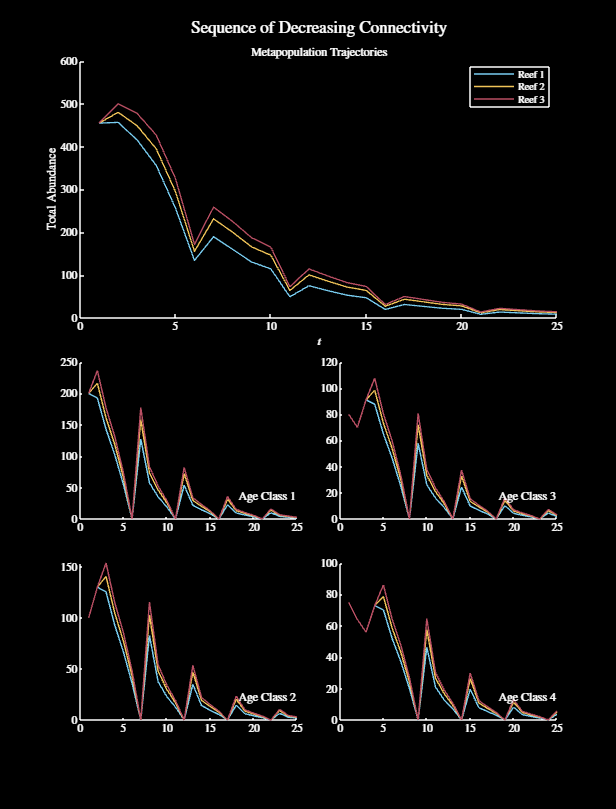

% let's first do a sequence of connectivity matrices which will approach 0
% over a time of 5 years, to show the fluctuations in the populations
% trajectories
tMax = 25;
conMat = 0.8 * [0.1, 0.007, 0.001; 0.09, 0.12, 0.09; 0, 0.09, 0.15];
nStages = 5;
conMatCell = cell(1, nStages);
for i = 1:nStages
    conMatCell{i} =  (nStages - i) * conMat / (nStages - 1);
end
popMat = baseMetapopModel(conMatCell, areaVec, popInit, tMax, specStruct);

% visualise the stuff -> create a function
tL = visualiseMetapop(popMat, 1:tMax);
title(tL, "Sequence of Decreasing Connectivity")
darkFig(tL)
figResize(1.6, 1.4)

### Connectivity Shuts Off After 10 Years

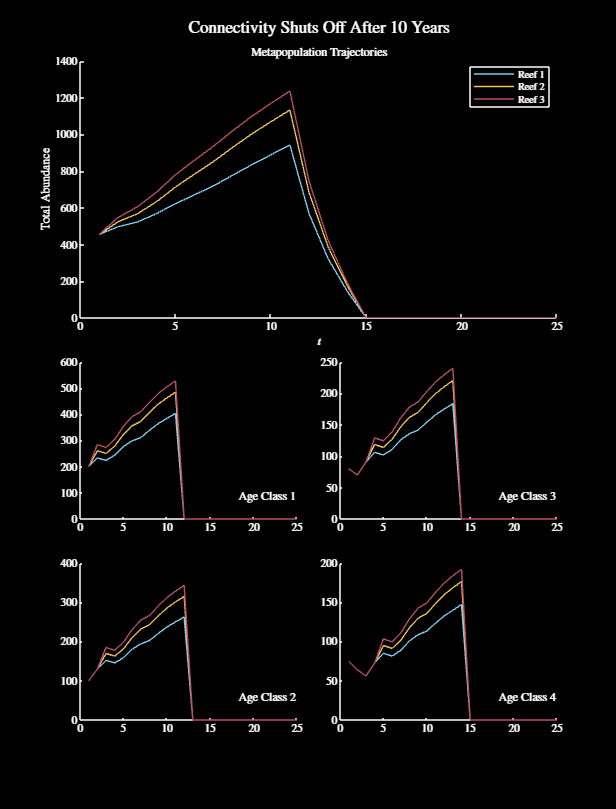

% next, let's do an example where connectivity shuts off after 10 years
tMax = 25;
conMat = [0.1, 0.007, 0.001; 0.09, 0.12, 0.09; 0, 0.09, 0.15];
nStages = tMax;
conMatCell = cell(1, nStages);
for i = 1:nStages
    if i <= 10
        conMatCell{i} =  conMat;
    else
        conMatCell{i} =  zeros(size(conMat));
    end
end
popMat = baseMetapopModel(conMatCell, areaVec, popInit, tMax, specStruct);

% visualise the stuff -> create a function
tL = visualiseMetapop(popMat, 1:tMax);
title(tL, "Connectivity Shuts Off After 10 Years")
darkFig(tL)
figResize(1.75)

### Connectivity vs No Connectivity Sequence

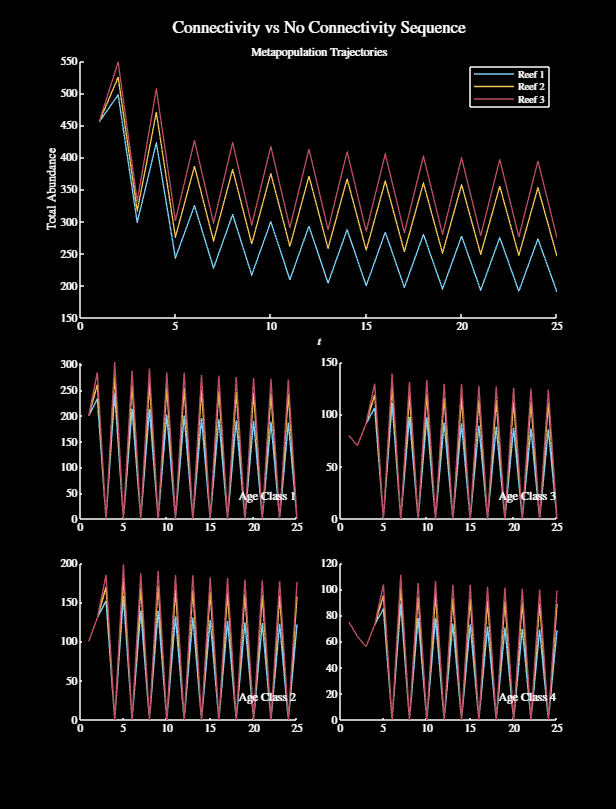

% next, let's do an example where connectivity shuts off after 10 years
tMax = 25;
conMat = [0.1, 0.007, 0.001; 0.09, 0.12, 0.09; 0, 0.09, 0.15];
nStages = tMax;
conMatCell = cell(1, 2);
conMatCell{1} = conMat;
conMatCell{2} = 0 * conMat;
popMat = baseMetapopModel(conMatCell, areaVec, popInit, tMax, specStruct);

% visualise the stuff -> create a function
tL = visualiseMetapop(popMat, 1:tMax);
title(tL, "Connectivity vs No Connectivity Sequence")
darkFig(tL)
figResize(1.75)

### Random Connectivity vs No Connectivity

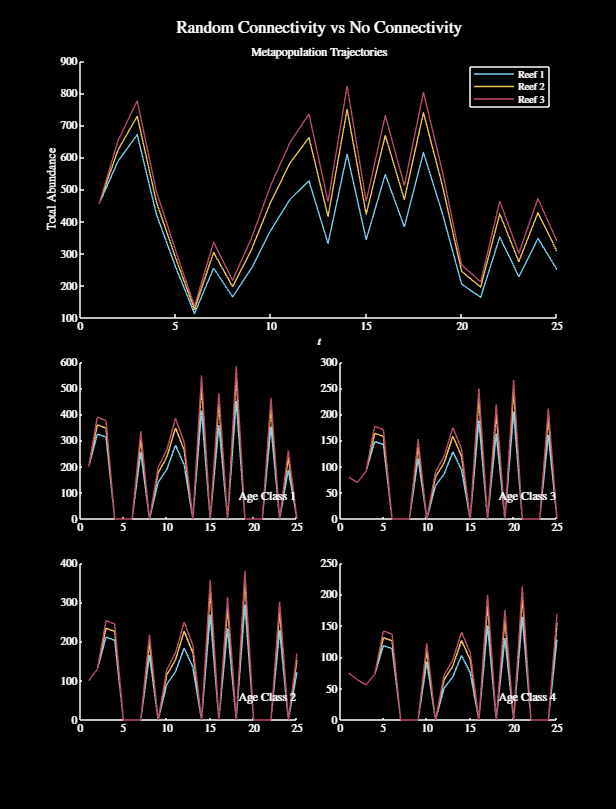

% next, let's do an example where connectivity shuts off after 10 years
tMax = 25;
conMat = 1.5 * [0.1, 0.007, 0.001; 0.09, 0.12, 0.09; 0, 0.09, 0.15];
nStages = tMax;
conMatCell = cell(1, 2);
conMatCell{1} = conMat;
conMatCell{2} = 0 * conMat;
randStruct.randType = "randSelection";
popMat = baseMetapopModel(conMatCell, areaVec, popInit, tMax, ...
    specStruct, randStruct);

% visualise the stuff -> create a function
tL = visualiseMetapop(popMat, 1:tMax);
title(tL, "Random Connectivity vs No Connectivity")
darkFig(tL)
figResize(1.75)

## Loading In Coral Trout Data

% cd ../Data/'Coral Trout'/

% gonna leave this for now, need the crcb_domain file from Mike

## Plotting Tools

% while the connectivity data is downloading, I'm going to go find and list
% some of the useful visualisation functions I've written previously which
% I can use here

### plotConMatSummary()

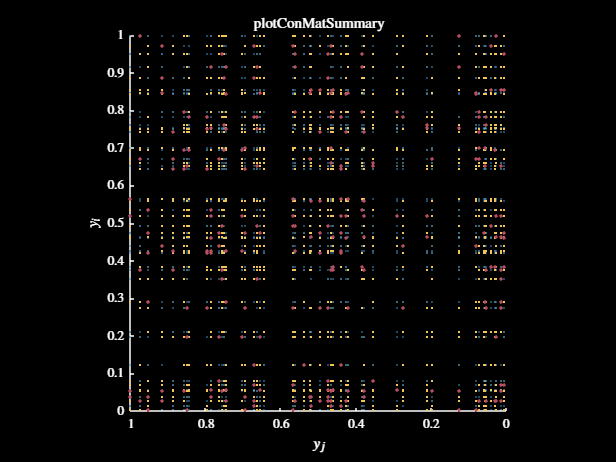

nNodes = 50;
conMat = 0.025 * (rand(nNodes) - 0.1);
conMat(conMat < 0) = 0;
centroids = rand(nNodes, 2);
figure
plotConMatSummary(conMat, centroids)
darkFig()
title("plotConMatSummary")
ylabel("$y_{i}$")
xlabel("$y_{j}$")

### plotDiagVals()

plotDiagVals()

## MPT Decision Coding

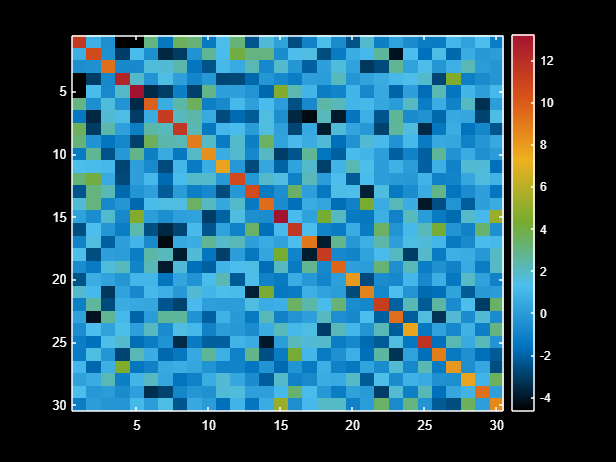

% I would like to check somewhere if the form for the portfolio variance
% actually holds up in practice if you know the covariances between all the
% time series, or if it is instead just a theoretical thing


% at some point I really need to test my assumptions about applying the MPT
% form for portfolio variance once the weights w_i are binary for a
% discrete decision space (I think this is still fine provided that the
% returns and variances are defined in this context)

% simulate an MPT problem
nAssets = 30;
rng(1)
covMat = 2 * rand(nAssets, nAssets) - 1;
covMat = covMat' * covMat;
variances = diag(covMat);
expReturns = 8 + rand(nAssets, 1) + 4 * sqrt(variances);

% make plots of the covariances
figure
imagesc(covMat)
colormap(myColourMap())
colorbar
darkFig()


% simulate some time series data
data = mvnrnd(expReturns, covMat, 100)';

% determine the observed expected returns and variances
expReturnsObs = mean(data, 2);
variancesObs = var(data, [], 2);

% run the MPT code for 3 different weightings - for expected return only,
% variance only and a midpoint
[maxExpPort, maxExpRet, maxExpVar] = applyMPT(data, 1);
[mixedPort, mixedExpRet, mixedVar] = applyMPT(data, 0.5);
[minVarPort, minVarRet, minVarVar] = applyMPT(data, 0);

% also, determine the pareto - optimal front
weights = linspace(0, 1, 101);
paretoData = zeros(length(weights), 2);
for i = 1:length(weights)
    [~, paretoData(i, 1), paretoData(i, 2)] = applyMPT(data, weights(i));
end

% plot the assets along with the portfolios
figure
hold on
plot(variancesObs, expReturnsObs, '.', 'color', getColour('b'), 'MarkerSize', 12)
plot(paretoData(:, 2), paretoData(:, 1), 'k', ...
    'LineWidth', 1)
% plot(paretoData(:, 2), paretoData(:, 1), 'k.', 'MarkerSize', 5)
plot(maxExpVar, maxExpRet, '.', 'color', getColour('r'), 'MarkerSize', 18)
plot(mixedVar, mixedExpRet, '.', 'color', getColour('o'), 'MarkerSize', 18)
plot(minVarVar, minVarRet, '.', 'color', getColour('g'), 'MarkerSize', 18)
axis padded
xlabel('Variance')
ylabel('Expected Return')
title('MPT Visualisation')
legend('Assets', 'Pareto Opt. Front', 'Max. Exp. Ret.', ...
    '0.5 Weighting', 'Min. Var.', 'location', 'southwest')
setFontSize(13)

[test1, test2] = max(expReturnsObs)

test1 = 23.9684

test2 = 5

variancesObs(test2)

ans = 15.1747

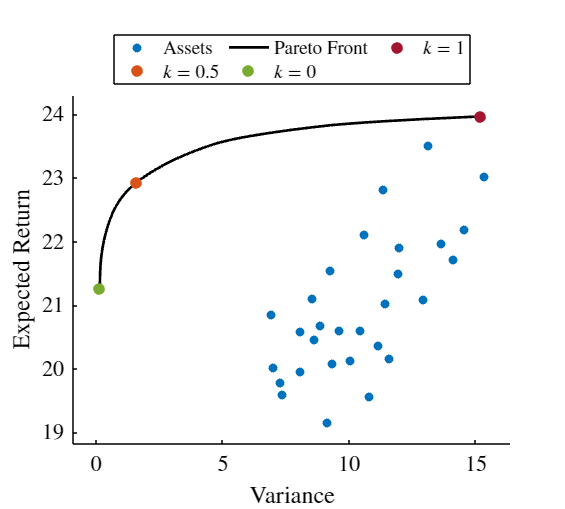


% save figure for progress report
set(gcf, 'InvertHardcopy', 'off')
% set(gcf, "color", [1, 1, 1])
set(gca, "color", 'w')
var1 = gca;
var1.YColor = 'k';
var1.XColor = 'k';
set(lg, 'Color', 'w')
lg.TextColor = 'k';
lg.EdgeColor = 'k';

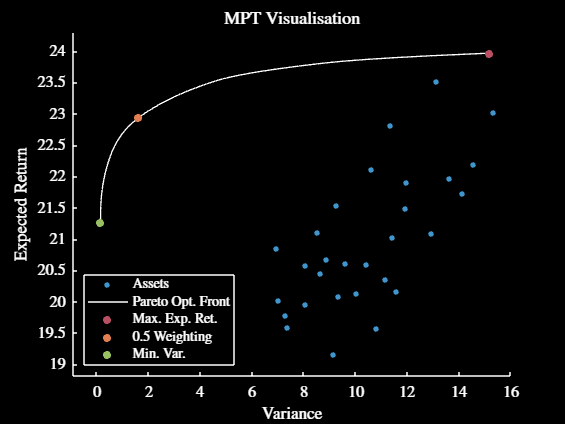

saveFig("MPTExample")

% save a dark mode of the figure too
darkFig()
saveFig("MPTExampleDM")

% make a plot for the presentation
tSize = 15;
figure
hold on
plot(variancesObs, expReturnsObs, '.', 'color', getColour('b'), 'MarkerSize', 20)
plot(paretoData(:, 2), paretoData(:, 1), 'k', ...
    'LineWidth', 2)
plot(maxExpVar, maxExpRet, '.', 'color', getColour('r'), 'MarkerSize', 26)
plot(mixedVar, mixedExpRet, '.', 'color', getColour('o'), 'MarkerSize', 26)
plot(minVarVar, minVarRet, '.', 'color', getColour('g'), 'MarkerSize', 26)
axis padded
xlabel('Variance', 'FontSize', tSize)
ylabel('Expected Return', 'FontSize', tSize)
lg = legend('Assets', 'Pareto Front', '$k = 1$', ...
    '$k = 0.5$', '$k = 0$', 'location', 'northoutside', 'Orientation', ...
    'horizontal');
lg.NumColumns = 3;
setFontSize(18)
figResize(1.2)
set(gcf, 'InvertHardcopy', 'off')
% set(gcf, "color", [1, 1, 1])
set(gca, "color", 'w')
var1 = gca;
var1.YColor = 'k';
var1.XColor = 'k';
set(lg, 'Color', 'w')
lg.TextColor = 'k';
lg.EdgeColor = 'k';

% save figure for progress report
saveFig("MPTExamplePP")

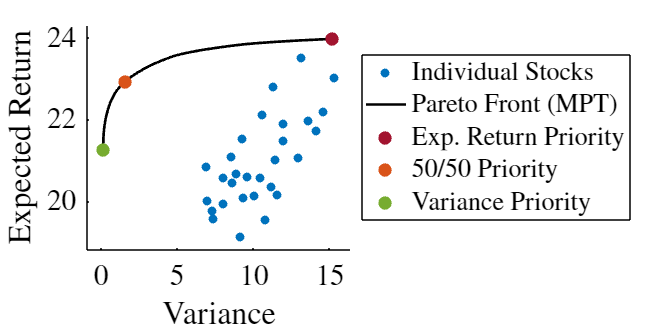

% make a plot for the presentation
tSize = 15;
figure
hold on
plot(variancesObs, expReturnsObs, '.', 'color', getColour('b'), 'MarkerSize', 20)
plot(paretoData(:, 2), paretoData(:, 1), 'k', ...
    'LineWidth', 2)
plot(maxExpVar, maxExpRet, '.', 'color', getColour('r'), 'MarkerSize', 30)
plot(mixedVar, mixedExpRet, '.', 'color', getColour('o'), 'MarkerSize', 30)
plot(minVarVar, minVarRet, '.', 'color', getColour('g'), 'MarkerSize', 30)
axis padded
xlabel('Variance')
ylabel('Expected Return')
lg = legend('Individual Stocks', 'Pareto Front (MPT)', 'Exp. Return Priority', ...
    '50/50 Priority', 'Variance Priority', 'location', 'eastoutside', 'Orientation', ...
    'vertical');
lg.NumColumns = 1;
setFontSize(24)
figResize(1.2, 1.8)
lightFig()

% save figure for progress report
saveFig("MPTExamplePP2")

clear nAssets covMat data

## Loading in Trout Data

% because I'm impatient, let's see if I can figure out some code which can
% do what I need lmao

% can use a Voronoi diagram to do this assignment bullshit lfg
cd ../Data/Full_GBR_Plectropomus/
load crcb_domain_full.mat centroid
cd ../../Code/

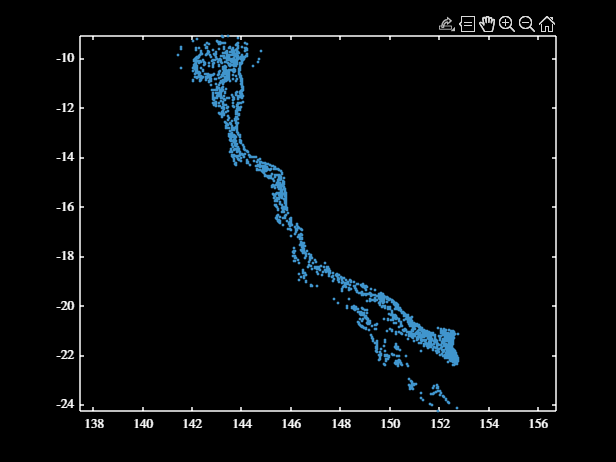

% let's now plot the centroids
figure
plot(centroid(:, 1), centroid(:, 2), '.')
axis equal
darkFig()

% because there are dumbass NaNs in the centroids, I'm going to remove all
% points which are NaNs
length(centroid)

ans = 2165

nonNanPoints = ~isnan(centroid(:, 1));
centroid = centroid(nonNanPoints, :);
nonNanPoints = ~isnan(centroid(:, 2));
centroid = centroid(nonNanPoints, :);
length(centroid)

ans = 2157

clear nanPoints

% note - I will later need to do this again for the connectivity matrices,
% as they will assumedly have blank rows due to their centroids being NaNs

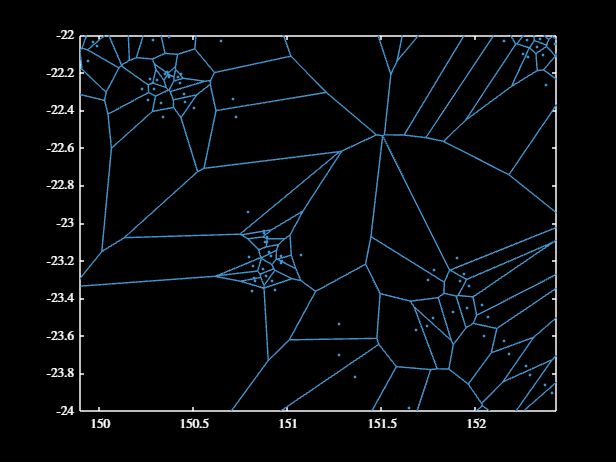

% alright - let's attempt to construct a voronoi diagram of these bad boys,
% althought I certainly forsee this being a huge fuckaround
voronoi(centroid(:, 1), centroid(:, 2))
axis([150, 152, -24, -22])
axis equal
darkFig()
% saveCoolFig("voronoiGBR1")


% great, that is cool but how do I actually get the regions back from this
% silly function fml

% look at the voronoiDiagram() function and the delaunayTriangulation()
% functions because they could be cool and good potentially 

delTriang = delaunayTriangulation(centroid);
[vorVert, vorInd] = voronoiDiagram(delTriang);

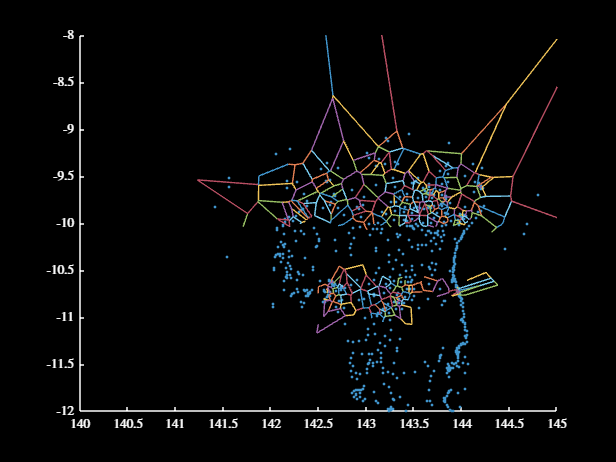

figure
hold on
plot(centroid(:, 1), centroid(:, 2), '.')
for r = 1:200
    plot(vorVert(vorInd{r}, 1), vorVert(vorInd{r}, 2))
end
axis([140, 145, -12, -8])
darkFig()

% saveCoolFig("VoronoiGBR3")

% before doing too much else I need to get rid of the godforsaken Infs at
% the start of this array, and then update the vorInd vec accordingly
vorVert = vorVert(2:end, :);
dumbassPoints = [];
for r = 1:length(vorInd)

    % check for the dumbass sections that reference 1
    if sum(vorInd{r} == 1) > 0
        ind = vorInd{r} ~= 1;
        vorInd{r} = vorInd{r}(ind);
        dumbassPoints = [dumbassPoints, r];
    end

    % reduce the rest of the indices
    vorInd{r} = vorInd{r} - 1;

end

% let's grab all of the points into a little search - ey thing
searchDistCell = cell(1, length(centroid));
for r = 1:length(centroid)
    searchDistCell{r} = cat(2, ...
        [vorVert(vorInd{r}, 1); vorVert(vorInd{r}(1), 1)], ...
        [vorVert(vorInd{r}, 2); vorVert(vorInd{r}(1), 2)]);
end

% % plot the dumbass points regions
% figure
% hold on
% plot(centroid(:, 1), centroid(:, 2), '.')
% for i = 1:length(dumbassPoints)
%     plot(searchDistCell{i}(:, 1), searchDistCell{i}(:, 2))
% end
% axis equal
% darkFig()

sum(isnan(centroid))

ans =      8     8


sum(centroid == inf)

ans =      0     0



% this whole section was a giant failure so I have given up on trying to
% get it to work well, just gonna run it brute force on my PC for now, at
% least I go some cool figures out of it I guess

% however, I still need to assign the centroids to the right reefs, so I
% will do that now just in a brute force manner, 2000 points getting
% assigned shouldn't take that long
% figure
% plotGBRShape(GBRShapeLL)

% anyway, will write code now to give us a good ol mapping
troutMapping = zeros(1, length(centroid));
for i = 1:length(centroid)

    % search through all the reefs because I'm too lazy to do anything else
    for r = 1:length(GBRShapeLL)
        if inpolygon(centroid(i, 1), centroid(i, 2), GBRShapeLL(r).X, ...
            GBRShapeLL(r).Y)
            troutMapping(i) = r;
        end
    end

end

% let's look at how many didn't get assigned, and look if any doubled up
nUnassigned = length(troutMapping) - sum(troutMapping > 0)

nUnassigned = 565

nDoubleUps = 2 * (length(troutMapping(troutMapping > 0)) ...
    - length(unique(troutMapping(troutMapping > 0))))

nDoubleUps = 18

clear nUnassigned nDoubleUps

% get fucked there are double ups, and I will need to plot them to see
unassigned = troutMapping == 0;
doubleUps = zeros(1, length(centroid));
for r = 1:length(centroid)
    if sum(troutMapping(r) == troutMapping) > 1 && troutMapping(r) > 0
        doubleUps(r) = 1;
    end
end
doubleUps = doubleUps > 0;
sum(doubleUps)

ans = 18

% plot that shit dawg
% figure
% plotGBRShape(GBRShapeLL, [], [], [], 'k')
% hold on 
% for r = 1:length(centroid)
%     if troutMapping(r) == 0
%         plot(centroid(r, 1), centroid(r, 2), 'rx')
%     elseif doubleUps(r) == 1
%         plot(centroid(r, 1), centroid(r, 2), 'g+')
%     end
% end
% axis equal

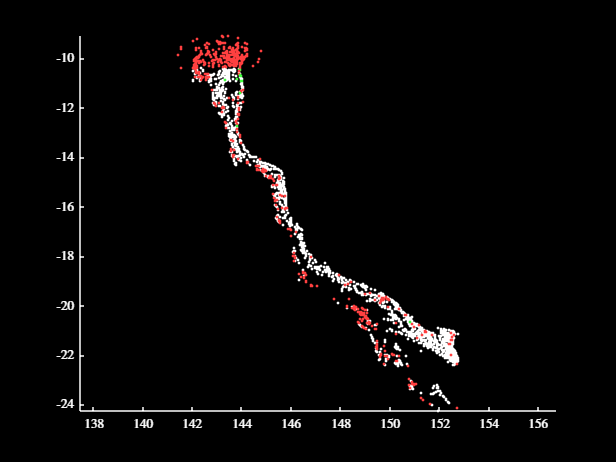

% honestly, given we are only going to use a subset of these anyway, I feel
% like there's not much point in matching these other ones up anyway
figure
hold on
plot(centroid(:, 1), centroid(:, 2), 'k.')
for r = 1:length(troutMapping)
    if doubleUps(r) == 1
        plot(centroid(r, 1), centroid(r, 2), 'g.')
    elseif unassigned(r) == 1
        plot(centroid(r, 1), centroid(r, 2), 'r.')
    end
end
axis equal
darkFig()

## Checking Trout Data

% want to ensure that the data is ok, so let's check some things here just
% to make sure


## Coding Decision Methods

% first, let's grab code that can choose matrices based on a number of
% factors -> not sure if I should have one global method which has a "type"
% argument or what, I suppose that probably would be the easiest solution
% though

% for that method, could probably use a structure as an input which could
% hold multiple things inside it I guess

% first of all, we can just grab code from the COTS stuff for any of the
% network metrics

% shit - I probably will want to add suffixes for how some of the decisions
% are made maybe - e.g. suffixes for when the matrices are to be averaged,
% e.g. outDegAverage etc etc
chooseReefs()